Exam 2/Final Project Preparation

Justin Merkel, Michael Lawlor, Preston Witte, Parker Wilson

Due Date:   Thursday, December 1

%Clearing Previous Code
clc

What power (in horsepower) and what speed will the input shaft of your team’s power train be transferring through the train?

Power=15; %Horsepower
RPMG=1500; %RPM Of Gear
Torque=Power/RPMG*(5250); %Ft-lb

Material Properties

All properties come from AISI 1020 Steel

Sut=60.90; %kpsi
Sy=50.80; %kpsi
v=0.29;
E=29000; %kpsi
Hb=111; %Brinell Hardness

What type of gears will your team specify?

% Gear Type: Spur Gear
% The gear will be on the input shaft

Calculate the forces on the gear and pinion.  Indicate whether the gear or pinon is on the input shaft and provide a Free Body Diagram of each.  Clearly indicate the direction of the pitch line velocity.

Attach a copy of your team’s gear design results and provide values for the following metrics.

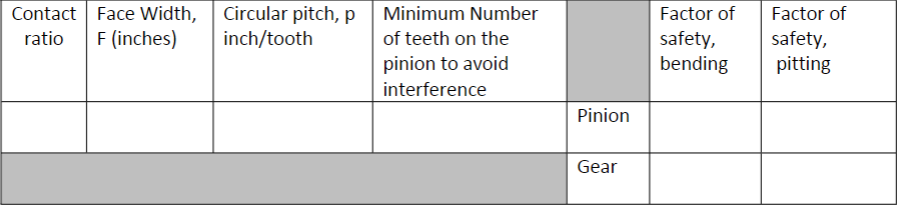

Inputting variables from a gear and pinion selected from  Rush Gears

The selected gear has part number F1030

The selected pinion has part number F1015

Ng=30;
Np=15;
Pitch_Angle=20;
Pitch_Angle=Pitch_Angle*pi/180;
Pitch=10;
K=1;
PD=3;
Face_Width=1;

Premptive Geometry Calculations

Circular_Pitch=pi*PD/Ng;

m=Ng/Np;

dg=Ng/Pitch;

dp=Np/Pitch;

Addendum=1/Pitch;

Dedendum=1.25/Pitch;

Rgo=(dg/2) + Addendum;

Rbg=(dg/2)*cos(Pitch_Angle);

Rpo=(dp/2)+Addendum;

Rbp=(dp/2)*cos(Pitch_Angle);


Contact Length Formula

Z=sqrt(Rgo^2-Rbg^2)+sqrt(Rpo^2-Rbp^2)-((dg+dp)/2)*sin(Pitch_Angle);


Base Pitch Formula

Pb= (pi*dg/Ng)*cos(Pitch_Angle);

Contact Ratio Formula

CR=Z/Pb;

Minimum Number of Teeth

Rounding up for a whole number

Npmin=((2*K)/((1+2*m)*(sin(Pitch_Angle))^2))*(m+sqrt(m^2+(1+2*m)*(sin(Pitch_Angle))^2));
Npmin=ceil(Npmin);

Face Width Parameters

 A conditional check to make sure face width is within and 3p and 5p

if Face_Width>=3*Circular_Pitch  
    if Face_Width<=5*Circular_Pitch
    disp('The Face Width F is within the Allowed Values of 3p and 5p')
    end
else
    disp('The Face Width F is not within the allowed Values of 3p and 5p')
end

The Face Width F is within the Allowed Values of 3p and 5p


Calculations of Gear Forces/Loads

RPMP=RPMG*Ng/Np; % Pinion Speed
VelocityGear=pi*(dg*RPMG)/12;
Wt_Gear=33000*Power/VelocityGear; %Gear Transmitted Load
Wr_Gear=Wt_Gear*tan(Pitch_Angle); %Gear Radial Load
Wa_Gear=0; %Gear Thrust Load

VelocityPinion=pi*dp*RPMP/12;
Wt_Pinion=Power/VelocityPinion; %Pinion Transmitted Load
Wr_Pinion=Wt_Pinion*tan(Pitch_Angle); %Pinion Radial Load
Wa_Pinion=0; % Pinion Thrust Load

Factor of Safety Due to Pitting

Mn=1;
Mg=Ng/Np;
Cf=1;
Cp=(1/(pi*((1-v^2)/E)+(1-v^2)/E))^(0.5);
Ko=1;
Kt=1;
Kv=1.56;
Ks=1;
Km=1.305;
I=((cos(Pitch_Angle)*sin(Pitch_Angle))/2*Mn)*(Mg/Mg+1);

Stress_C_Gear=Cp*sqrt(Wt_Gear*Ko*Kv*Ks*(Km/(dp*Face_Width))*(Cf/I));

Stress_C_Pinion=1000*(Cp*sqrt(Wt_Pinion*Ko*Kv*Ks*(Km/(dp*Face_Width))*(Cf/I)));


Sc=322*Hb+29100;
Kt=1;
%assuming 99.99 percent reliability
Kr=1.5;
%Assuming 100000 cycles
Zn=2.466*100000^(-0.056);
Ch=1;

FS_Pitting_Gear=((Sc*Zn*Ch)/(Kt*Kr))/Stress_C_Gear;

FS_Pitting_Pinion=((Sc*Zn*Ch)/(Kt*Kr))/Stress_C_Pinion;

Factor of Safety Due to Bending

Kt=1;
%assuming 99.99 percent reliability
Kr=1.5;
Ko=1;
Kv=1.56;
Ks=1;
Km=1.305;
Kb=1;
J_Gear=0.355;
J_Pinion=0.25;

%Assuming Stress Cycle Safety Factor Yn=1
Yn=1;

Stress_Bend_Gear=Wt_Gear*Ko*Kv*Ks*dp*Km*Kb/(Face_Width*J_Gear);
Stress_Bend_Pinion=1000*Wt_Pinion*Ko*Kv*Ks*dp*Km*Kb/(Face_Width*J_Pinion);
St=14423.3;

FS_Bending_Gear=((St*Yn)/(Kt*Kr))/Stress_Bend_Gear;
FS_Bending_Pinion=((St*Yn)/(Kt*Kr))/Stress_Bend_Pinion;

Free Body Diagram

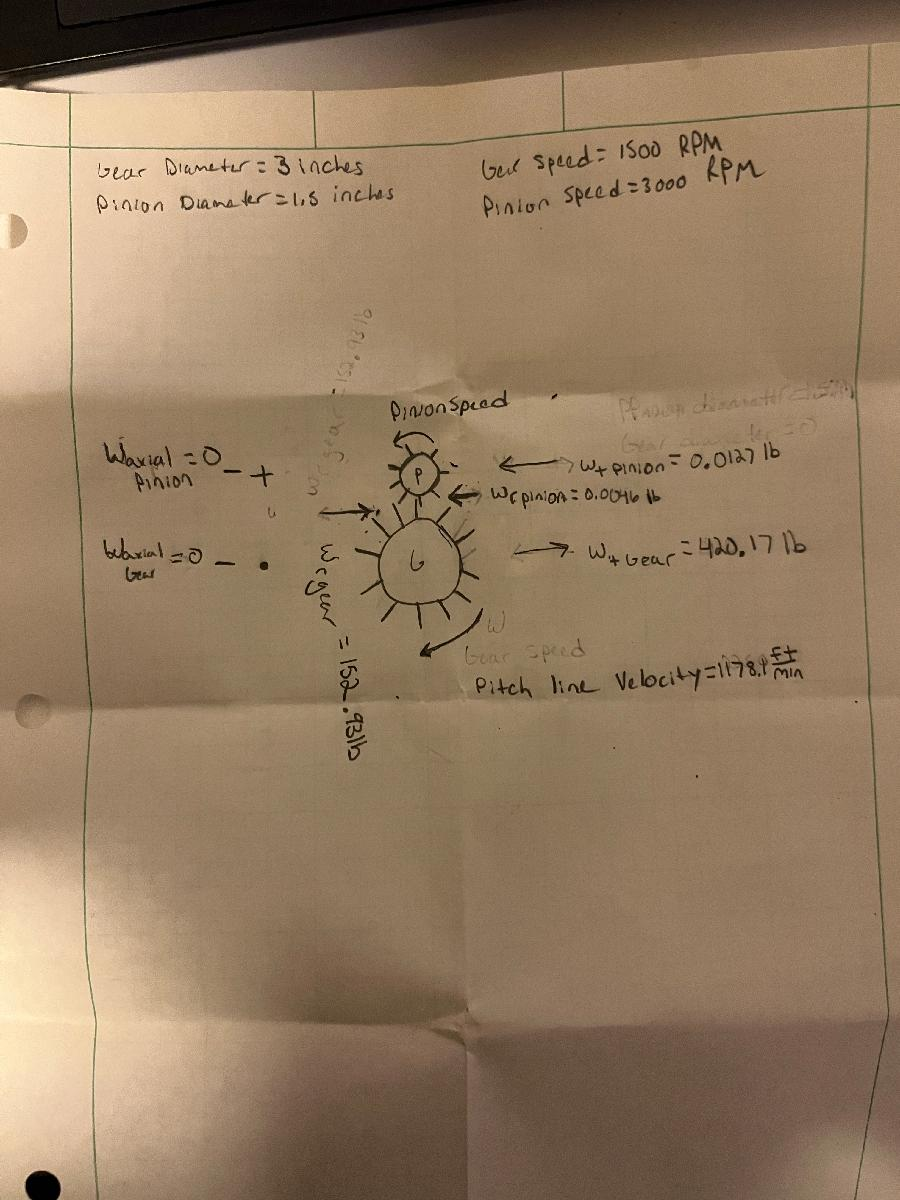

Vp=2*pi*(dg/2)*RPMG/12;

%Displaying the values required for submission

u=['The Pitch Line Velocity is ', num2str(Vp), ' Ft/min'];
disp(u)

The Pitch velocity is 1178.0972 Ft/min



r=['The Factor of Safety against Bending for the Gear is ', num2str(FS_Bending_Gear)];
disp(r)

The Factor of Safety against Bending for the Gear is 2.6604



s=['The Factor of Safety against Pitting for the Pinion is ', num2str(FS_Pitting_Gear)];
disp(x)

The Circular Pitch of the pinion is 10



t=['The Factor of Safety against Bending for the Pinion is ', num2str(FS_Bending_Pinion)];
disp(t)

The Factor of Safety against Bending for the Pinion is 61.8268



x=['The Factor of Safety against Pitting for the Pinion is ', num2str(FS_Pitting_Pinion)];
disp(x)

The Factor of Safety against Pitting for the Pinion is 2.7594


y=['The Face Width of the pinion is ', num2str(Face_Width), ' Inch'];
disp(y)

The Face Width of the pinion is 1 Inches


w=['The Contact Ratio is ', num2str(CR)];
disp(w)

The Contact Ratio is 1.5675


q=['The minimumn number of pinion teeth to avoid interference is ', num2str(Npmin)];
disp(q)

The minimumn number of pinion teeth to avoid interference is 15
